# Exam 2019 

Name : Anton Sakarias Rørbæk Sihm

Student nr: 201504954

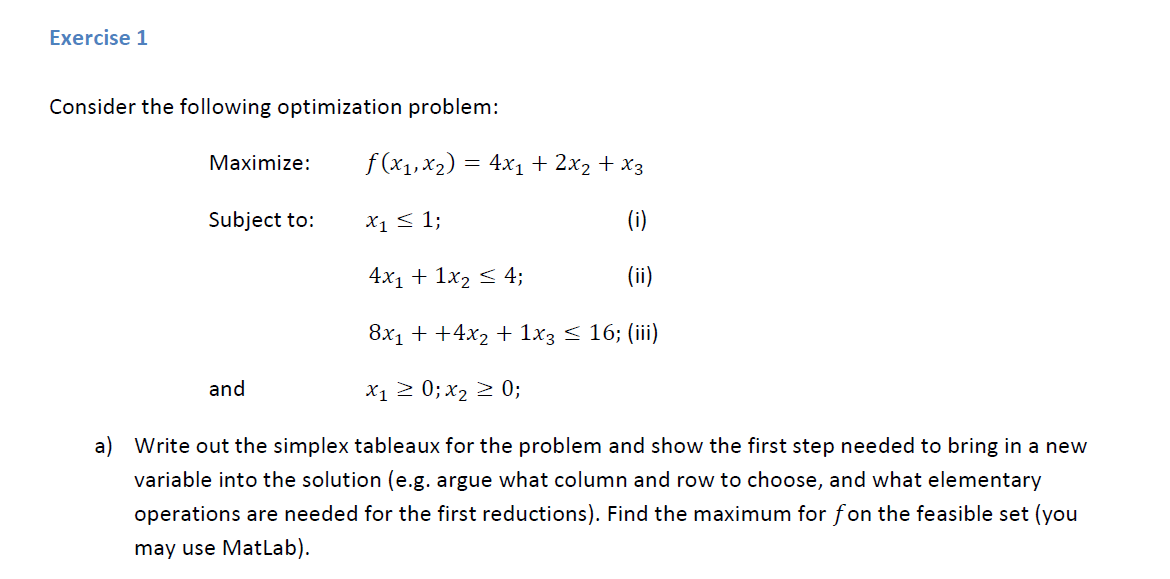

% Simplex tuable for the problem  
% Step change inquality to equality by adding slacks var
%    x1   x2,   x3, s1   s2   s3    M     B  
A = [1,    0,   0,   1,   0,   0,   0,   1;
     4,    1,   0,   0,   1,   0,   0,   4;
     8,   4,    1,   0,   0,   1,   0,   16;
     -4,  -2,  -1,  0,   0,   0,    1,   0]

A =        1              0              0              1              0              0              0              1       
       4              1              0              0              1              0              0              4       
       8              4              1              0              0              1              0             16       
      -4             -2             -1              0              0              0              1              0       


% Step two, find most negative --> they are equal -- we take x1
% Step three a positive ratio than is smallets 
% B/entry  for all entries
% 1/1 = 1  |   4/4 = 1    |    16/8 = 2     --> pivot on R1 or R2 --> we take R1

% R3 - 8R1
A(3,:) = A(3,:) - 8*A(1,:);

% R2 - 4R1
A(2,:) = A(2,:) - 4*A(1,:);

% R4 + 4R1
A(4,:) = A(4,:) + 4*A(1,:)

A =        1              0              0              1              0              0              0              1       
       0              1              0             -4              1              0              0              0       
       0              4              1             -8              0              1              0              8       
       0             -2             -1              4              0              0              1              4       


% This is the first iteration
% ion of the simplix algorithm.
% lets finish the rest computationally
x1 = optimvar('x1');
x2 = optimvar('x2');
x3 = optimvar('x3');

prob = optimproblem('Objective', 4*x1 +2*x2 + x3,'ObjectiveSense','max');
prob.Constraints.c1 = x1  <= 1;
prob.Constraints.c2 = 4*x1 + x2 <= 4;
prob.Constraints.c3 = 8*x1 + 4*x2 + x3 <= 16;
prob.Constraints.c4 = x1 >= 0;
prob.Constraints.c5 = x2 >= 0;

problem = prob2struct(prob);
[sol,fval,exitflag,output] = linprog(problem);

Optimal solution found.



max_value = 4*0 + 2*0 + 16;
fprintf("Our maxpoint is [x1, x2, x3]  = [ %.2f,  %.2f, %.2f] with max value : %.2f ", sol, max_value );

Our maxpoint is [x1, x2, x3]  = [ 0.00,  0.00, 16.00] with max value : 16.00 

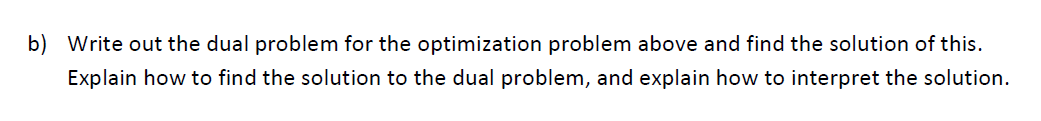

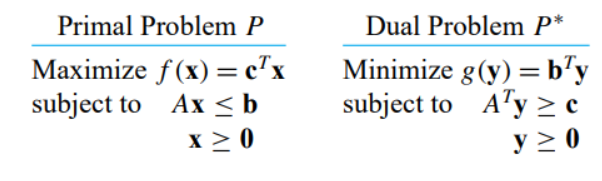

We can convert the the maximum problem (Primal problem) into its dual problem which minimizes the following:


$$A^T =$$

$$\;\left\lbrack \begin{array}{ccc}
1 & 4 & 8\\
0 & 1 & 4\\
0 & 0 & 1
\end{array}\right\rbrack \;\;\;$$



$$g\left(y_1 ,y_2 ,y_3 \right)=1*y_1 +4*y_2 +16*y_3$$


subject to:

 
$$y_1 \;+4y_2 +8y_3 \ge 4$$



$$1y_2 +4y_3 \ge 2$$



$$\;y_3 \ge 1$$


$y_1 \ge 0$ , $y_2 \ge 0$, $y_3 \ge 0$

% By solving the primal problem, we also obtain a solution for minimize in
% the dual problem, from the slack variables.

matrix=[1 0 0 1 0 0;
        4 1 0 0 1 0; 
        8 4 1 0 0 1];

b=[1;4;16];
c=-[4;2;1;0;0;0];
v=[4;5;6];

simplex(c,matrix,b,v,1)

 
Initial tableau:
       1              0              0              1              0              0              1       
       4              1              0              0              1              0              4       
       8              4              1              0              0              1             16       
      -4             -2             -1              0              0              0              0       

Pivot point:
       1              1       

New tableau:
       1              0              0              1              0              0              1       
       0              1              0             -4              1              0              0       
       0              4              1             -8              0              1              8       
       0             -2             -1              4              0              0              4       

Pivot point:
       2              2       

New tableau:
       1       

ans =        0       
       0       
      16       
       1       
       4       
       0       



$$1*y_1 +4*y_2 +16*y_3$$


minimize_point = [0,0,1]

minimize_point =        0              0              1       


clear g y1 y2 y3
syms y1 y2 y3
g = y1 + 4*y2 + 16*y3; 
y1 = minimize_point(1);
y2 = minimize_point(2);
y3 = minimize_point(3);
min_value = subs(g)

$$min\_value = 16$$

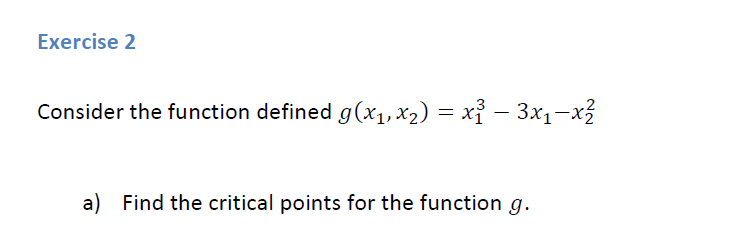

If we calculate the gradiant and set it equal to zero, we can solve for critical points : $\nabla f\left(x\right)=0$ 

clearvars;
syms x1 x2
g = x1^3 - 3*x1-x2^2;

gradiant_g = gradient(g, [x1, x2]);
gradiant_g_at_0 = gradiant_g == 0

$$gradiant\_g\_at\_0 = \left(\begin{array}{c} 3\,{x_{1}}^{2}-3=0\\ -2\,x_{2}=0 \end{array}\right)$$

[x1,x2] = solve([gradiant_g_at_0], [x1, x2])

$$x1 = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

$$x2 = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

point1 = [x1(1), x2(1)], point2 = [x1(2), x2(2)]

$$point1 = \left(\begin{array}{cc} -1 & 0 \end{array}\right)$$

$$point2 = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

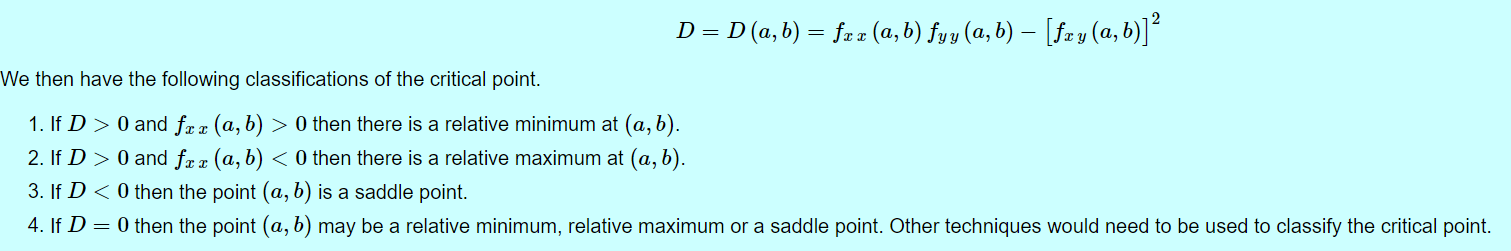

clear x1 x2
syms x1 x2

hessian_g = hessian(g,[x1,x2])

$$hessian\_g = \left(\begin{array}{cc} 6\,x_{1} & 0\\ 0 & -2 \end{array}\right)$$

D = hessian_g(1,1)*hessian_g(2,2)-(hessian_g(2,1))^2

$$D = -12\,x_{1}$$

fxx = hessian_g(1,1)

$$fxx = 6\,x_{1}$$

% point1
x1 = point1(1);
x2 = point1(2);

d_p1 = subs(D)

$$d\_p1 = 12$$

fxx_p1 = subs(fxx)

$$fxx\_p1 = -6$$

fprintf("Since D > 0 : %.3f > 0 and fxx < 0 : fxx < %.3f then point (%.3f, %.3f) is a local MAX",d_p1,fxx_p1, point1(1), point1(2));

Since D > 0 : 12.000 > 0 and fxx < 0 : fxx < -6.000 then point (-1.000, 0.000) is a local MAX

% point2
x1 = point2(1);
x2 = point2(2);
d_p2 = subs(D)

$$d\_p2 = -12$$

fxx_p2 = subs(fxx)

$$fxx\_p2 = 6$$

fprintf("Since D < 0 : %.3f < 0 then point (%.3f, %.3f) is a Saddle Point",d_p2, point2(1), point2(2));

Since D < 0 : -12.000 < 0 then point (1.000, 0.000) is a Saddle Point

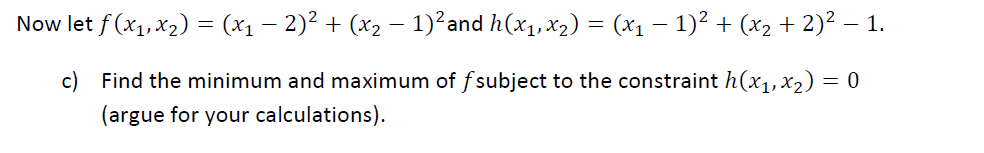

We will use the Lagrange multiplier for the problem


$$\nabla f\left(x\right)+\lambda *\nabla h\left(x\right)=0$$
 

We can solve the follwing problem by solving 3 linequeations with 3 uknowns

clearvars
syms x1 x2
f = (x1-2)^2 + (x2-1)^2;
gradiant_f = gradient(f, [x1,x2]);

clear x1 x2
syms x1 x2 lambda
h = (x1 - 1)^2 + (x2 + 2)^2 - 1 

$$h = {\left(x_{1}-1\right)}^{2}+{\left(x_{2}+2\right)}^{2}-1$$

gradiant_h = gradient(h, [x1,x2])

$$gradiant\_h = \left(\begin{array}{c} 2\,x_{1}-2\\ 2\,x_{2}+4 \end{array}\right)$$

% Lagrange multiplier
Lagrange_multiplier = gradiant_f + lambda*gradiant_h == 0

$$Lagrange\_multiplier = \left(\begin{array}{c} 2\,x_{1}+\lambda \,\left(2\,x_{1}-2\right)-4=0\\ 2\,x_{2}+\lambda \,\left(2\,x_{2}+4\right)-2=0 \end{array}\right)$$

% we now have 2 equation and 3 unknowns
% we can use the fuction h = 0 as the last one:
equation1 = Lagrange_multiplier(1)

$$equation1 = 2\,x_{1}+\lambda \,\left(2\,x_{1}-2\right)-4=0$$

equation2 = Lagrange_multiplier(2)

$$equation2 = 2\,x_{2}+\lambda \,\left(2\,x_{2}+4\right)-2=0$$

equation3 = (x1 - 1)^2 + (x2 + 2)^2 - 1 == 0

$$equation3 = {\left(x_{1}-1\right)}^{2}+{\left(x_{2}+2\right)}^{2}-1=0$$

[x1,x2,lambda] = solve([equation1, equation2, equation3], [x1,x2, lambda]);
x1 = double(x1)

x1 =      949/721   
     493/721   


x2 = double(x2)

x2 =     -758/721   
   -2126/721   


lambda = double(lambda)

lambda =     3038/1405  
    -949/228   


% candidate coordinates 
s1 = [x1(1), x2(1)];
s2 = [x1(2), x2(2)];
% Solutions
%(x1-2)^2 + (x2-1)^2;
f1 = (s1(1)-2)^2 + (s1(2)-1)^2

f1 =     6569/1405  


f2 = (s2(1)-2)^2 + (s2(2)-1)^2

f2 =     1975/114   


fprintf("maximum: %.2f at point : (%.2f, %.2f) and minimum: %.2f at point (%.2f, %.2f)", f2, s2, f1, s1);

maximum: 17.32 at point : (0.68, -2.95) and minimum: 4.68 at point (1.32, -1.05)

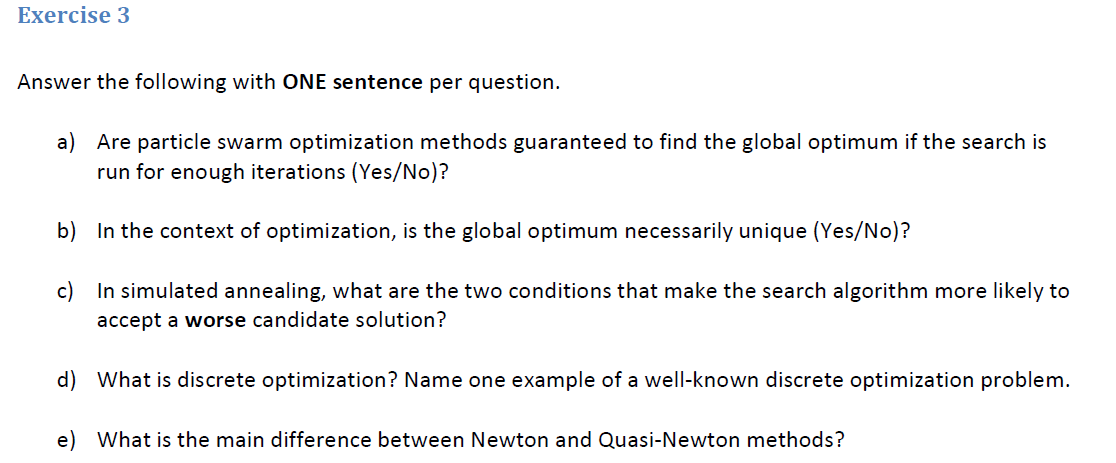

% a)
% No, even tho we run for a long times the algoritm is not 100% sure to converge for a global optimum. 

% b)
% No, there can in princible be a global opimum there can be achiceved
% multiple places with the exact same value. Fx max tempurature = 28, can
% maybe be found at diffent places if the temp is exact = 28.

% c)
% Iterations + temparature. If we have been running for at long time, and
% the temp is high, the algorithm is more likly for accept at worse
% candidate, to try and explore new candidate solutions

% d) Discrete optimazations only works on discrete variables. One example could be path finding 

% e) The main difference is that the newton method uses the Gradiant, which
% is recalculated each interation. The Quasi-newton uses at aproximation
% which is much faster for higher dimension problems.

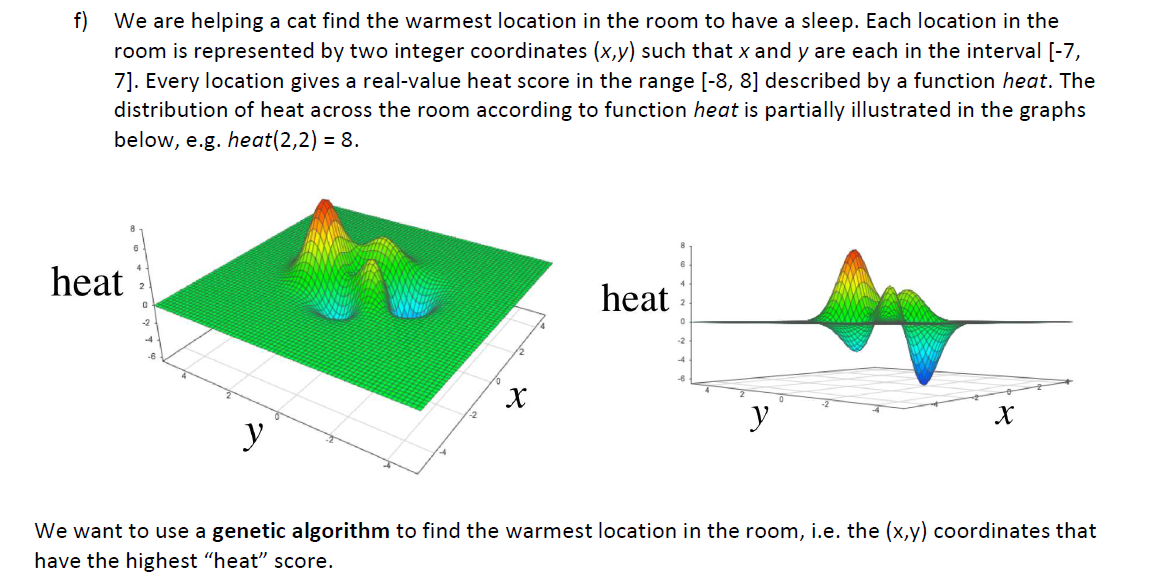

% Representation : x--> to binaray,   y--> to binary. Then contatenate x+y
% as a string sequence.
% Example could be the transformed cordinate into chromosone
%                                         x   y
% convertiong x,y : 1,1 = to bits:      00010001    

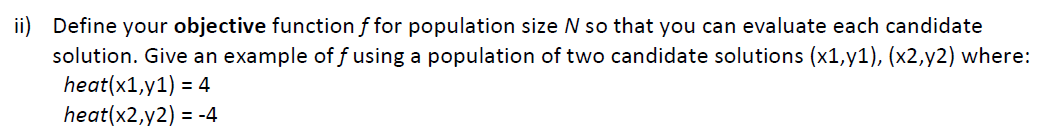

% c = chromosone, bin(x) --> converts x to binary format
% f(c) = heat(split(c, 1:4), split(c, 5:8))
% c1 = bin(x1) + bin(y1)
% c2 = bin(x2) + bin(y2)
% f(c1) = heat(split(c1, 1:4)), split(c1, 5:8)) = 4
% f(c2) = heat(split(c1, 1:4)), split(c1, 5:8)) =-4

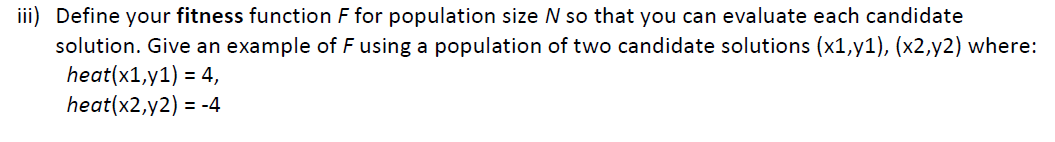

% c = chromosone
% fit(c) --> fitness funtion can be the heat(split(c1, 1:4))/8. This produces the fit or how good
% the candidate solution is. The output will be between -1,1 where 1 is the
% best possible given the contrains of heat lvl 8 is max.

% Assuming we have 2 good candidate solution which can form a parrent set.
% We can spawn a new child, which inherates the good fitness value from the
% parrents. The higher the fitness value is, the highere probalitity there
% are to some parents spawning childs.

% Example p is a parrent:
% p1 = 11100001
% p2 = 00101001


p1 = 11100001

p2 = 11100001

crossover --> first 4 genes from parrent1, and crossover the 4 last from parrent2

p1 = **1110**0001

p2 = 1110**0001**

child1 = **11100001**

child2 = 00011110

% Strategy:
% Since we no nothing about the envirements(where are high points are) we
% will use exploration. That we genatere the population randomly

% Step 1:
% Generate sample for unexplored regions (random)

% Step 2:
% Convert the x,y into its chromosome representation


% Step 3:
% Calculate the fitness value for each chromosome

% If any good cadidates that is -- a high fitness. Create new childrens and
% evaluate agian.



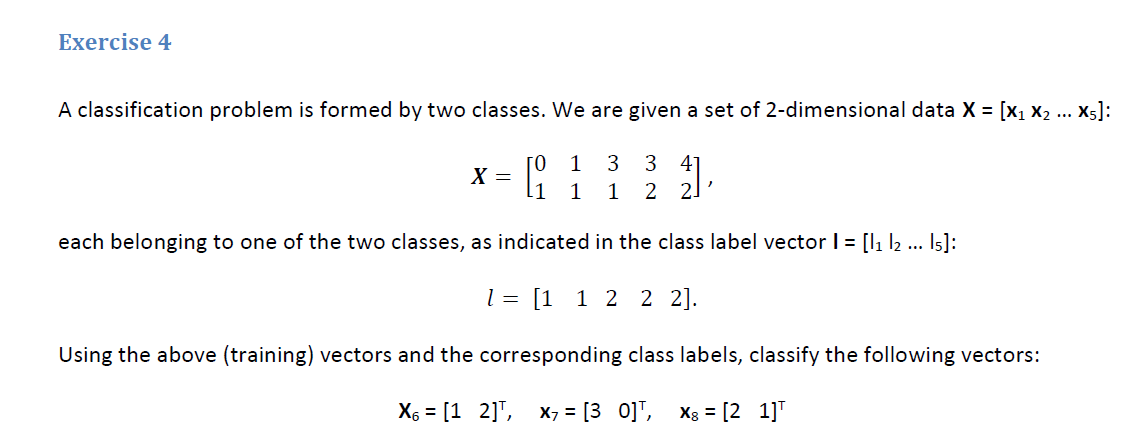

%For this I will use python.

I did the following in python. Th steps are as follows:

% Calculate the centroid for each class --> mean each x_i of each class
% Calculate the dist from test sample to each centroid
% Classify by taking the smallest dist to centroid.
% The python code can be seen as follows:

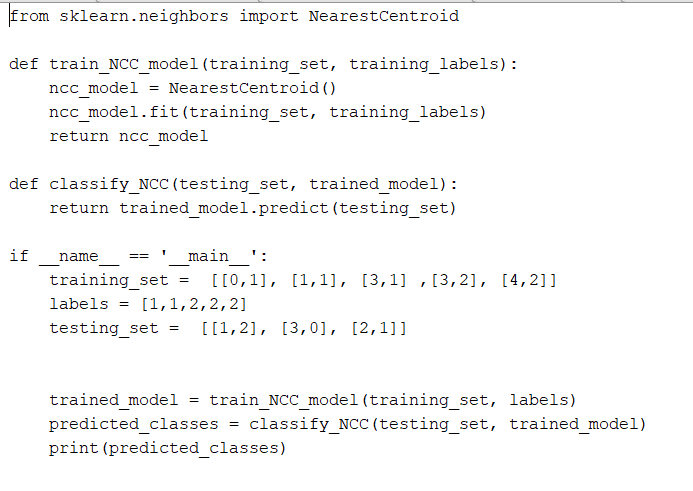

%  .\Nearest_Centroid.py  yields the prediction for x_i for i = 6, 7, 8.
%  prediction =  [1 2 2]

%Agian for this I will use python.

I did the following in python. Th steps are as follows:

% Calculate the dist to each class from the testing sample
% Classify by taking asking the k =1 neighbors for the class.
% vote from the set og neigbors, which is this case is only one.
% The python code can be seen as follows:

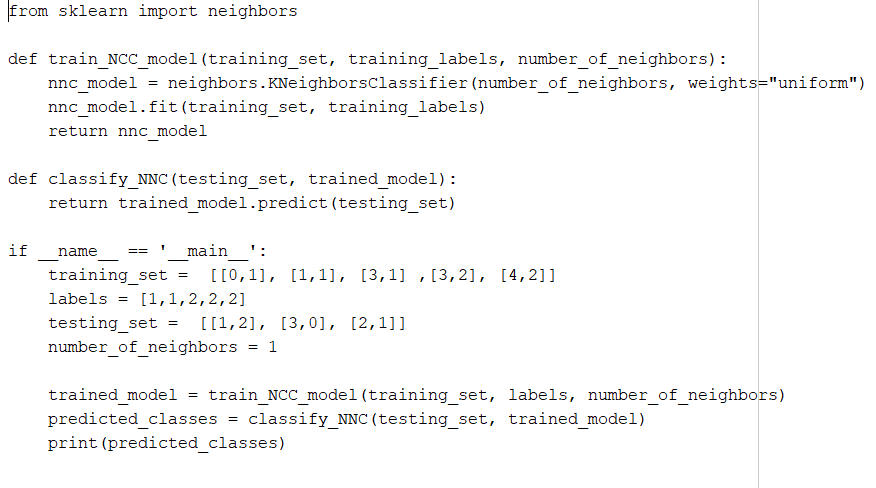

% .\Nearest_Neighbor.py yields the following prediction for x_i for i = % 6, 7, 8.
% prediction = [1 2 1]

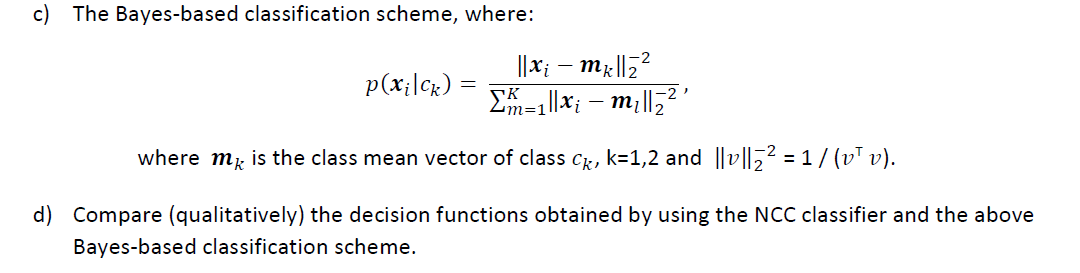

% TODO
% TODO
% TODO

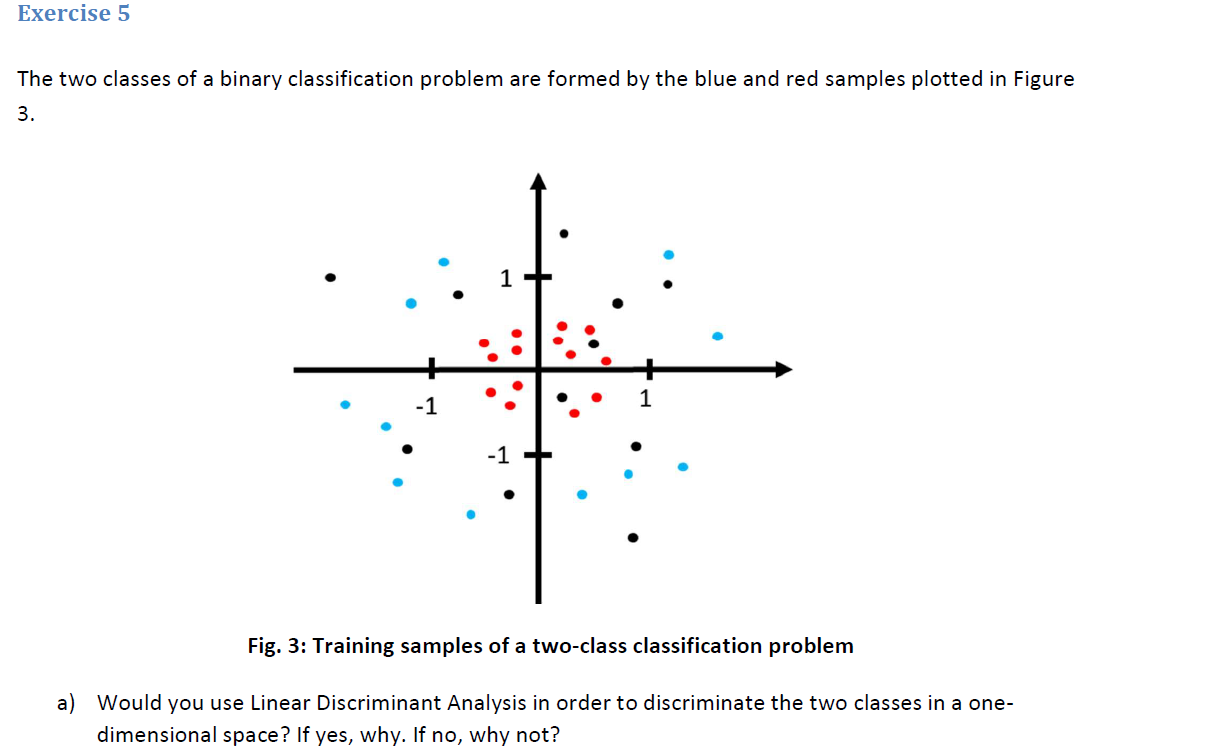

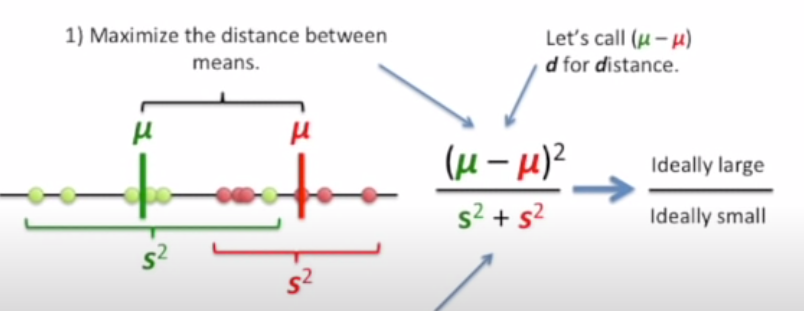

% Since the means for both classes seems very close, I whould not use LDA
% for this, since the distance between the two mean are very small swicth
% generates a bad classification between the classes. We usually want a big
% different between the means and a small scatter for both classes.
% So NO.

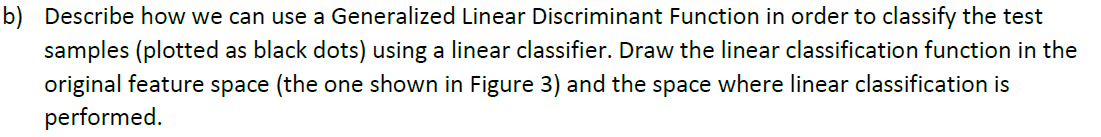

% Since the current domain is very bad for LDA, we can transform the data
% into antother domain where the mean is much better:
% f(x,y) --> f(x^2, y^2) makes a good space for the LDA
% f(x,y) --> to polar form  = R < Theta also makes a good space for LDA
% with the R values.

                                                **Current space                                                                                  x^2, y^2    space **

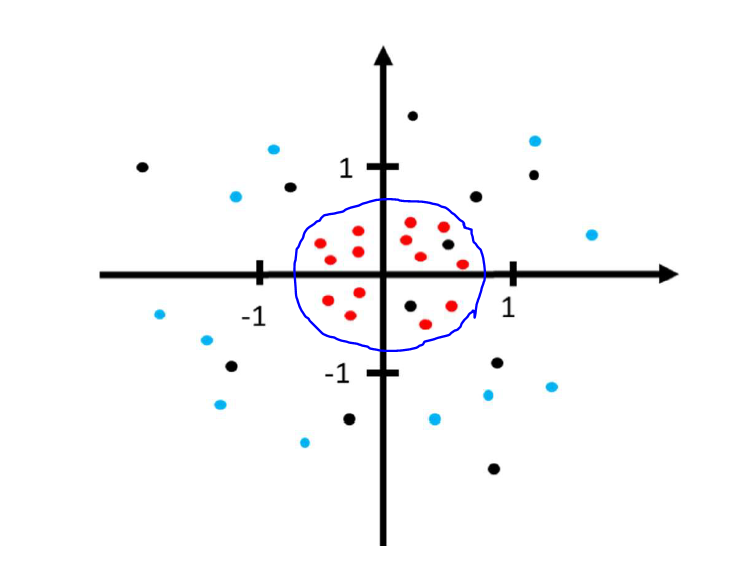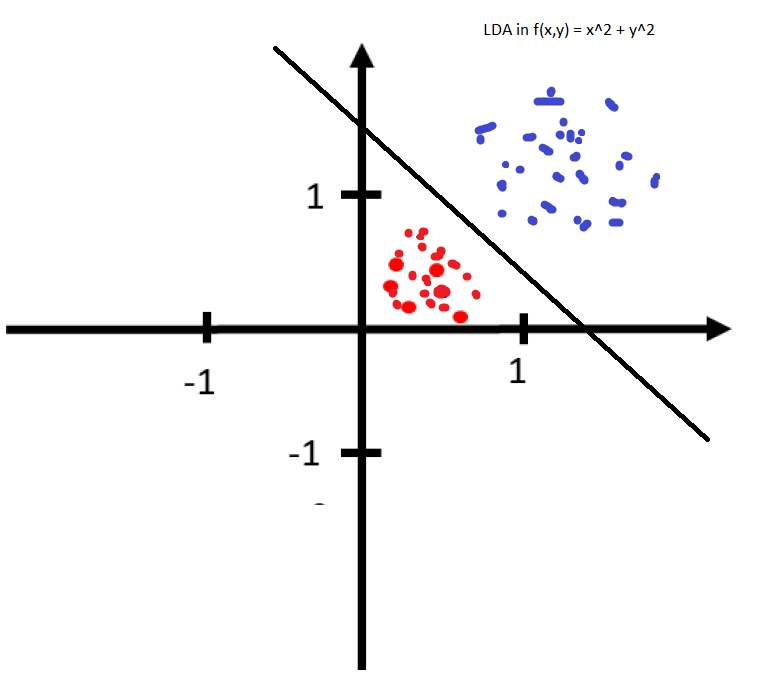

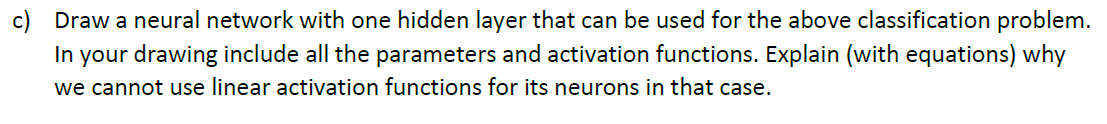

% I ) draw with http://alexlenail.me/NN-SVG/index.html
% We will have 1 hidden layer, and 2 outputs reasoned that we have 2 output
% classes. The neuron size for the hidden layer can be of any set, but it
% heavyly depends on the input problem.
% The input layer is the size of then dimension

% Input should be number of input values   (example Image of 10*10 gives 100 input)
% weigts are wrong.

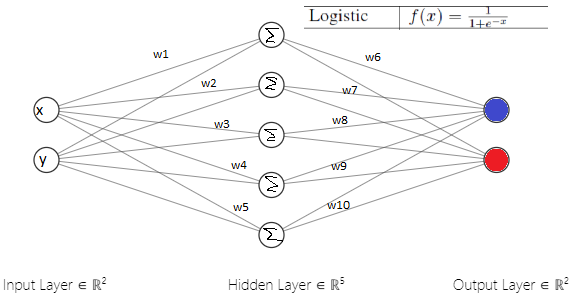

% II ) All layers of the neural network collapse into one, because a linear
% combination of linear functions is still a linear function. It does not matter
% how many hidden layers we have, the final activaition function wil just
% be a linear function of the first layer, mean the layers will colapse.


$$\begin{array}{l}
z=W_2 *y=W_2 *W_1 *x\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=W_3 *x
\end{array}$$


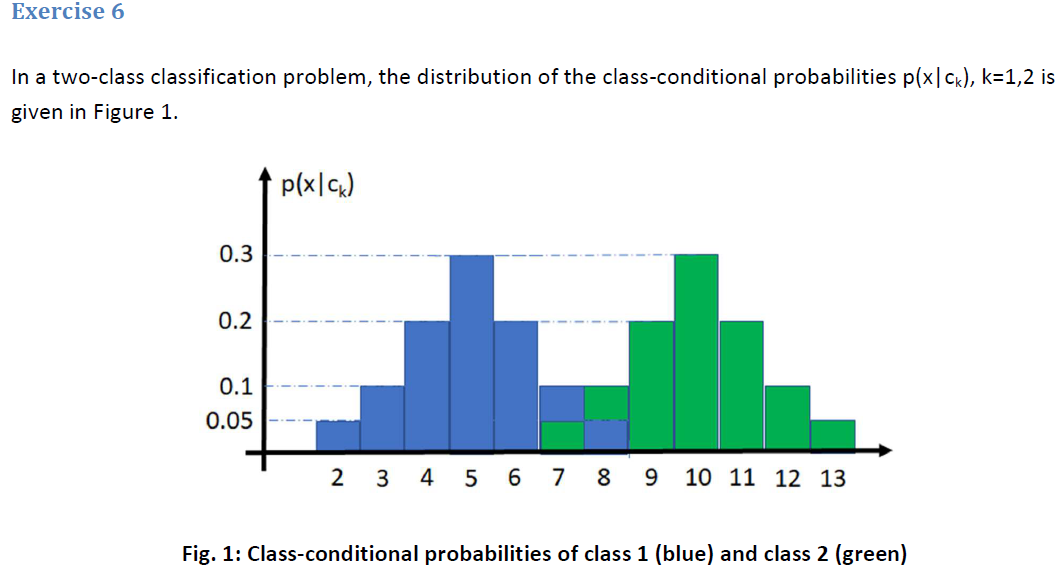

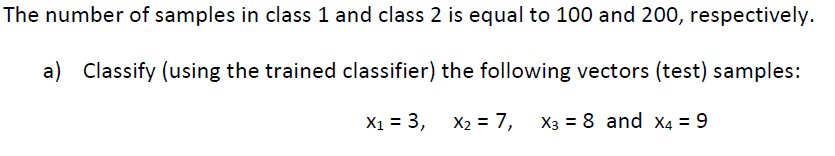

We will use the bayes formula to calculate the  $P\left(c_k \left|\;x\right.\right)$ since we alreaddy have $p\left(x\;\left|\;c_k \right.\right)$ given for every x in the trained model we can use bayers rule, to get $P\left(c_k \left|\;x\right.\right)$. Note that ine the decision function $P\left(x\right)$ gets canceled out:


$$P\left(c_k \left|x\;\right.\right)=\frac{P\left(x\left|c_k \;\right.\right)*P\left(c_k \right)}{P\left(x\right)}\;$$


We will use this decision function to decide the class:

$P\left(c_1 \left|x\;\right.\right)$> $P\left(c_2 \left|x\;\right.\right)$  

inserting from bayers we get:

 
$$\frac{P\left(x\left|c_1 \right.\right)*P\left(c_1 \right)}{P\left(x\right)}>\frac{P\left(x\left|c_2 \;\right.\right)*P\left(c_2 \right)}{P\left(x\right)}$$


Multiply by P(X), it cancels out.


$$P\left(x\left|c_1 \right.\right)*P\left(c_1 \right)>P\left(x\left|c_2 \;\right.\right)*P\left(c_2 \right)$$


% For 3=4, x=7, x=8, x=9
p_x_3_given_c1 = 0.1;
p_x_3_given_c2 = 0;

p_x_7_given_c1 = 0.1;
p_x_7_given_c2 = 0.05;

p_x_8_given_c1 = 0.05;
p_x_8_given_c2 = 0.1;

p_x_9_given_c1 = 0;
p_x_9_given_c2 = 0.2;

p_c1 = 100/300;
p_c2 = 200/300;

I will use the BayesTwoClassClassifer.m which i implmented for the classification.

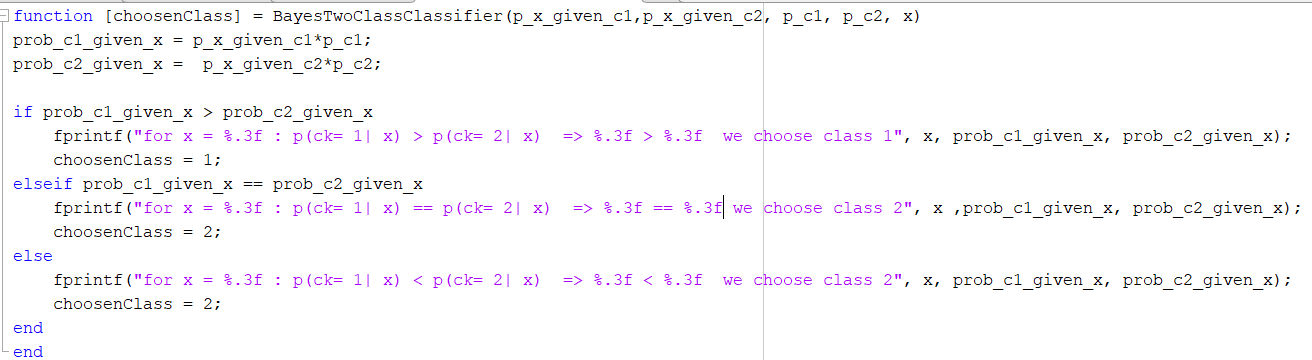

chossenClass_4 = BayesTwoClassClassifier(p_x_3_given_c1,p_x_3_given_c2,p_c1,p_c2,4);

for x = 4.000 : p(ck= 1| x) > p(ck= 2| x)  => 0.033 > 0.000  we choose class 1

chossenClass_7 = BayesTwoClassClassifier(p_x_7_given_c1,p_x_7_given_c2,p_c1,p_c2,7);

for x = 7.000 : p(ck= 1| x) == p(ck= 2| x)  => 0.033 == 0.033 we choose class 2

chossenClass_8 = BayesTwoClassClassifier(p_x_8_given_c1,p_x_8_given_c2,p_c1,p_c2,8);

for x = 8.000 : p(ck= 1| x) < p(ck= 2| x)  => 0.017 < 0.067  we choose class 2

chossenClass_9 = BayesTwoClassClassifier(p_x_9_given_c1,p_x_9_given_c2,p_c1,p_c2,9);

for x = 9.000 : p(ck= 1| x) < p(ck= 2| x)  => 0.000 < 0.133  we choose class 2

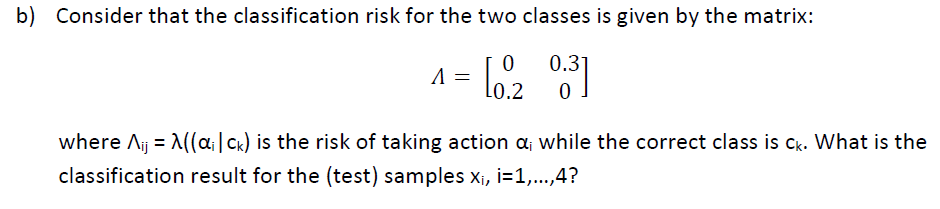

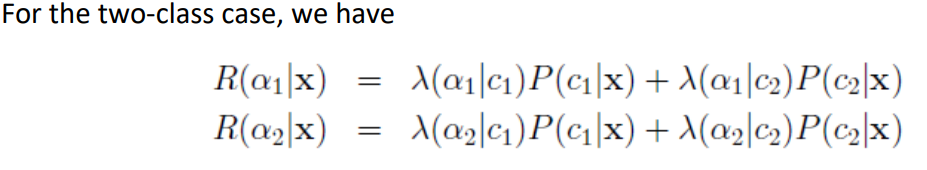

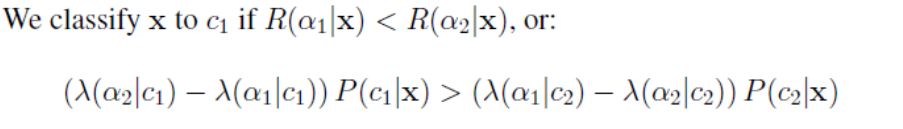

We will use the RiskClassifer.m which I implemented for the classification in matlab.

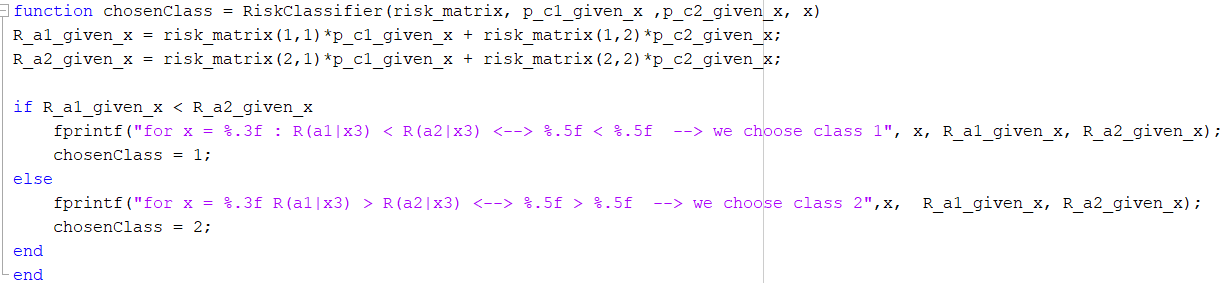

% I will assume that i = the i'th risk and for the j -> k-class
risk_matrix = [  0,  0.3;
               0.2,  0  ]

risk_matrix =        0              3/10    
       1/5            0       



% We need to calculate p(x_i) for i = 1,2,3,4 for the input value of the
% risk classifier

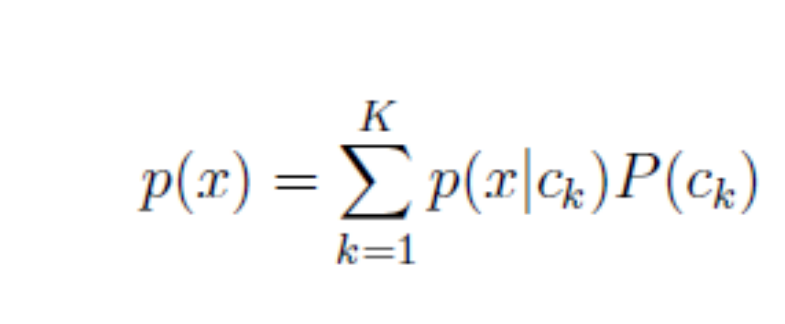

% The function for p(x) is implemented in CalcPx.m

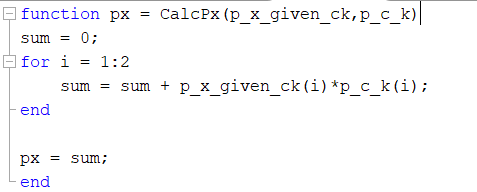

% for all
p_c_k = [p_c1, p_c2];

% x = 3
p_x3_given_ck = [p_x_3_given_c1, p_x_3_given_c2];
p_x3 = CalcPx(p_x3_given_ck,p_c_k );

% bayes
p_c1_given_x3 = (p_x_3_given_c1*p_c1)/p_x3;
p_c2_given_x3 = (p_x_3_given_c2*p_c2)/p_x3;
%classify
chosenClass_x4 = RiskClassifier(risk_matrix,p_c1_given_x3, p_c2_given_x3, 3);

for x = 3.000 : R(a1|x3) < R(a2|x3) <--> 0.00000 < 0.20000  --> we choose class 1

% x = 7
p_x7_given_ck = [p_x_7_given_c1, p_x_7_given_c2];
p_x7 = CalcPx(p_x7_given_ck,p_c_k );

% bayes
p_c1_given_x7 = (p_x_7_given_c1*p_c1)/p_x7;
p_c2_given_x7 = (p_x_7_given_c2*p_c2)/p_x7;
%classify
chosenClass_x7 = RiskClassifier(risk_matrix,p_c1_given_x7,p_c2_given_x7, 7);

for x = 7.000 R(a1|x3) > R(a2|x3) <--> 0.15000 > 0.10000  --> we choose class 2

% x = 8
p_x8_given_ck = [p_x_8_given_c1, p_x_8_given_c2];
p_x8 = CalcPx(p_x8_given_ck, p_c_k);

% bayes
p_c1_given_x8 = (p_x_8_given_c1*p_c1)/p_x8;
p_c2_given_x8 = (p_x_8_given_c2*p_c2)/p_x8;
%classify
chosenClass_x8 = RiskClassifier(risk_matrix,p_c1_given_x8,p_c2_given_x8, 8);

for x = 8.000 R(a1|x3) > R(a2|x3) <--> 0.24000 > 0.04000  --> we choose class 2

% x = 9
p_x9_given_ck = [p_x_9_given_c1, p_x_9_given_c2];
p_x9 = CalcPx(p_x9_given_ck, p_c_k);

% bayes
p_c1_given_x9 = (p_x_9_given_c1*p_c1)/p_x9;
p_c2_given_x9 = (p_x_9_given_c2*p_c2)/p_x9;
%classify
chosenClass_x9 = RiskClassifier(risk_matrix,p_c1_given_x9,p_c2_given_x9, 9);

for x = 9.000 R(a1|x3) > R(a2|x3) <--> 0.30000 > 0.00000  --> we choose class 2